# Quantum Probabilities

[*Matthias Wolff*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/prof-dr-ing-habil-matthias-wolff)**, Günther Wirsching**, *[*Markus Huber*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/dipl-math-markus-huber)**, *[*Peter beim Graben*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/dr-rer-nat-peter-beim-graben)**, and Ingo Schmitt**

* [BTU Cottbus-Senftenberg](https://www.b-tu.de/en/), ** KU Eichstätt-Ingolstadt

fock.addFockBoxPaths();

[**TODO**: Reproducing introductory example from [1].]

## Settings

% Angle of Clinton basis in degrees
alphaC = 0;

% Angle of Gore basis in degrees
alphaG = 45;

% Agreement with Clinton
pCy = 0.7;

% Plot vector label offsets (fine tuning for paper)
vlo = {[-0.05 0.10 0] [0.15 0 0] [0 0 0] [0 0 0]};          

%% Bases
fprintf('_________________________________________________________________');

_________________________________________________________________

fprintf('\nBases \n\n');


Bases 



fprintf('  Angle of Clinton basis: %g°\n',alphaC);

  Angle of Clinton basis: 0°


fprintf('  Angle of Gore basis   : %g°\n',alphaG);

  Angle of Gore basis   : 45°



% Hilbert space
b1 = fockobj.bket('1');
b2 = fockobj.bket('2');

% Clinton basis
RC = cos(alphaC*pi/180)*(b1*b1') - sin(alphaC*pi/180)*(b1*b2') ...
   + sin(alphaC*pi/180)*(b2*b1') + cos(alphaC*pi/180)*(b2*b2');
RC.name = 'Change-to-Clinton-basis operator';
Cy = RC*b1; Cy.name = '"Yes to Clinton" basis vector';                disp(Cy);

  fockobj

    Name: "Yes to Clinton" basis vector 
    Type: ket 

    (1,ε)               	1.000000


Cn = RC*b2; Cn.name = '"No to Clinton" basis vector';                 disp(Cn);

  fockobj

    Name: "No to Clinton" basis vector 
    Type: ket 

    (2,ε)               	1.000000



% Gore basis
RG = cos(alphaG*pi/180)*(b1*b1') - sin(alphaG*pi/180)*(b1*b2') ...
   + sin(alphaG*pi/180)*(b2*b1') + cos(alphaG*pi/180)*(b2*b2');
RG.name = 'Change-to-Gore-basis operator';
Gy = RG*b1; Gy.name = '"Yes to Gore" basis vector';                   disp(Gy);

  fockobj

    Name: "Yes to Gore" basis vector 
    Type: ket 

    (1,ε)               	0.707107
    (2,ε)               	0.707107


Gn = RG*b2; Gn.name = '"No to Gore" basis vector';                    disp(Gn);

  fockobj

    Name: "No to Gore" basis vector 
    Type: ket 

    (1,ε)               	-0.707107
    (2,ε)               	0.707107



% Projectors
Pcy = Cy*Cy'; Pcy.name = 'Proj. on "Yes to Clinton" basis vector';
Pcn = Cn*Cn'; Pcn.name = 'Proj. on "No to Clinton" basis vector';
Pgy = Gy*Gy'; Pgy.name = 'Proj. on "Yes to Gore" basis vector';
Pgn = Gn*Gn'; Pgn.name = 'Proj.on "No to Gore" basis vector';

## Belief State Without Context

fprintf('\n_________________________________________________________________');


_________________________________________________________________

fprintf('\nBelief State Without Context \n\n');


Belief State Without Context 




% Prepare belief state
S  = sqrt(pCy)*b1 + sqrt(1-pCy)*b2; S.name  = 'Belief state';         disp(S);

  fockobj

    Name: Belief state 
    Type: ket 

    (1,ε)               	0.836660
    (2,ε)               	0.547723


SC = inv(RC)*S; SC.name = 'Belief state on Clinton basis';            disp(SC);

  fockobj

    Name: Belief state on Clinton basis 
    Type: ket 

    (1,ε)               	0.836660
    (2,ε)               	0.547723


SG = inv(RG)*S; SG.name = 'Belief state on Gore basis';               disp(SG);

  fockobj

    Name: Belief state on Gore basis 
    Type: ket 

    (1,ε)               	0.978906
    (2,ε)               	-0.204310


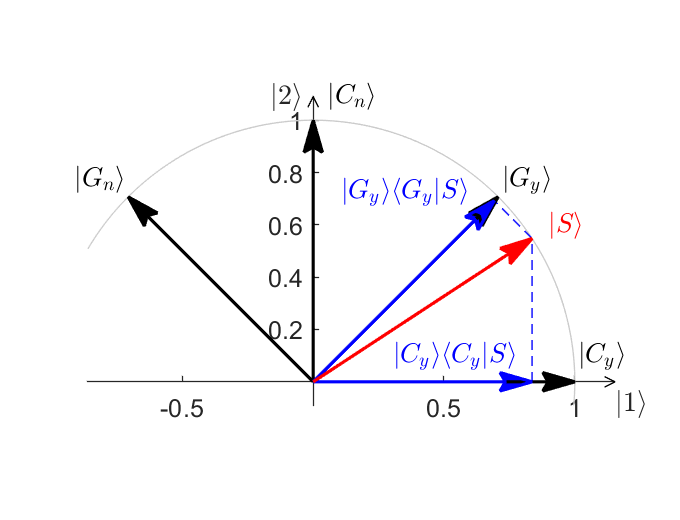


  Ratings:
    p(Cy) = 0.7000 ("Yes" to Clinton)
    p(Cn) = 0.3000 ("No" to Clinton)
    p(Gy) = 0.9583 ("Yes" to Gore)
    p(Gn) = 0.0417 ("No" to Clinton)



vlo = [ vlo(1,1:4) [-0.45 -0.03 0] [-0.45 0.1 0] [0 0 0] ];
[pCy,pCn,pGy,pGn] = beliefState(S,Pcy,Pgy,Cy,Cn,Gy,Gn,vlo);

Total Probabilities Without Context

fprintf('\n_________________________________________________________________');


_________________________________________________________________

fprintf('\nTotal Probabilities Without Context \n');


Total Probabilities Without Context 


fprintf('\n  Ratings:\n');


  Ratings:


fprintf('    p(Cy) = %0.4f ("Yes" to Clinton)\n',pCy);

    p(Cy) = 0.7000 ("Yes" to Clinton)


fprintf('    p(Cn) = %0.4f ("No" to Clinton)\n' ,pCn);

    p(Cn) = 0.3000 ("No" to Clinton)


fprintf('    p(Gy) = %0.4f ("Yes" to Gore)\n'   ,pGy);

    p(Gy) = 0.9583 ("Yes" to Gore)


fprintf('    p(Gn) = %0.4f ("Yes" to Gore)\n'   ,pGn);

    p(Gn) = 0.0417 ("Yes" to Gore)


## Belief State After Having Judged Clinton

% Belief State After Having Said "yes" to Clinton
fprintf('\n_________________________________________________________________');


_________________________________________________________________

fprintf('\nBelief State After Having Said "Yes" to Clinton \n\n');


Belief State After Having Said "Yes" to Clinton 




S  = Cy;        S.name  = 'Belief state';                             disp(S);

  fockobj

    Name: Belief state 
    Type: ket 

    (1,ε)               	1.000000


SC = inv(RC)*S; SC.name = 'Belief state on Clinton basis';            disp(SC);

  fockobj

    Name: Belief state on Clinton basis 
    Type: ket 

    (1,ε)               	1.000000


SG = inv(RG)*S; SG.name = 'Belief state on Gore basis';               disp(SG);

  fockobj

    Name: Belief state on Gore basis 
    Type: ket 

    (1,ε)               	0.707107
    (2,ε)               	-0.707107


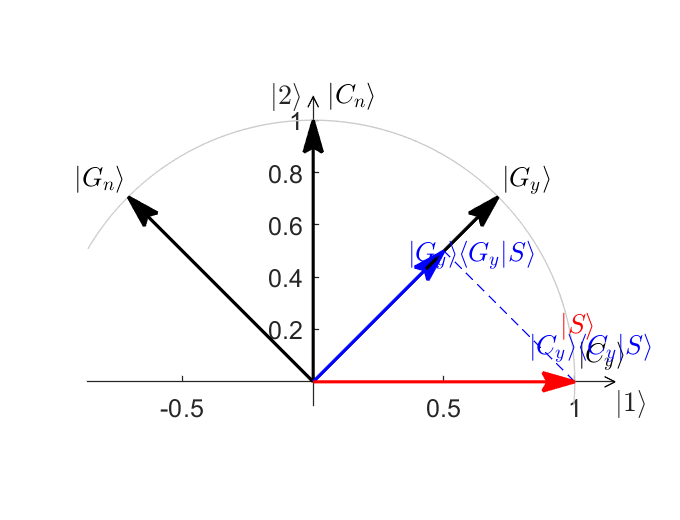


  Ratings:
    p(Cy) = 1.0000 ("Yes" to Clinton)
    p(Cn) = 0.0000 ("No" to Clinton)
    p(Gy) = 0.5000 ("Yes" to Gore)
    p(Gn) = 0.5000 ("No" to Clinton)



vlo = [ vlo(1,1:4) [0 -0.08 0] [-0.09 0.13 0] [-0.14 0.21 0] ];
[~,~,pCyGy,~] = beliefState(S,Pcy,Pgy,Cy,Cn,Gy,Gn,vlo);


% Belief State After Having Said "no" to Clinton
S = Cn;
pCnGy = (S'*Gy)^2;

## Belief State After Having Judged Gore

% Belief State After Having Said "Yes" to Gore
fprintf('\n_________________________________________________________________');


_________________________________________________________________

fprintf('\nBelief State After Having Said "Yes" to Gore \n\n');


Belief State After Having Said "Yes" to Gore 




S  = Gy;        S.name  = 'Belief state';                             disp(S);

  fockobj

    Name: Belief state 
    Type: ket 

    (1,ε)               	0.707107
    (2,ε)               	0.707107


SC = inv(RC)*S; SC.name = 'Belief state on Clinton basis';            disp(SC);

  fockobj

    Name: Belief state on Clinton basis 
    Type: ket 

    (1,ε)               	0.707107
    (2,ε)               	0.707107


SG = inv(RG)*S; SG.name = 'Belief state on Gore basis';               disp(SG);

  fockobj

    Name: Belief state on Gore basis 
    Type: ket 

    (1,ε)               	1.000000


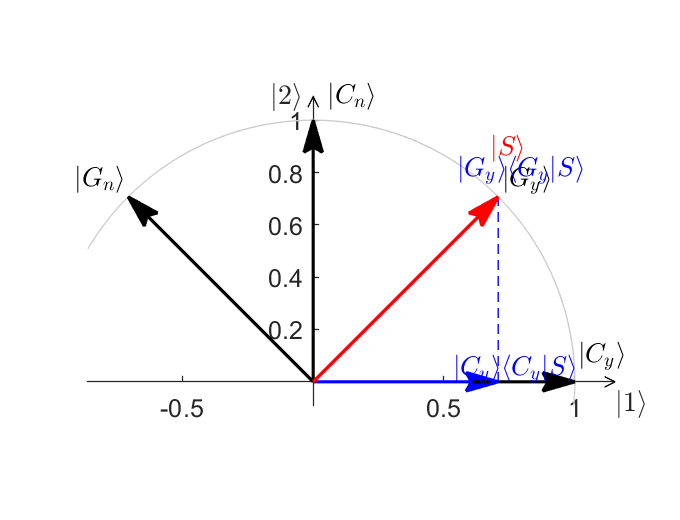


  Ratings:
    p(Cy) = 0.5000 ("Yes" to Clinton)
    p(Cn) = 0.5000 ("No" to Clinton)
    p(Gy) = 1.0000 ("Yes" to Gore)
    p(Gn) = 0.0000 ("No" to Clinton)



vlo = [ vlo(1,1:4) [-0.02 0.04 0] [-0.09 0.05 0] [-0.07 0.12 0] ];
[pGyCy,~,~,~] = beliefState(S,Pcy,Pgy,Cy,Cn,Gy,Gn,vlo);


% Belief State After Having Said "no" to Gore
S = Gn;
pGnCy = (S'*Cy)^2;

## Total Probabilities With Context

fprintf('\n_________________________________________________________________');


_________________________________________________________________

fprintf('\nTotal Probabilities With Context \n');


Total Probabilities With Context 


fprintf('\n  Ratings:\n');


  Ratings:


fprintf('    p(Cy) = %0.4f ("Yes" to Clinton)\n',pGy*pGyCy    +(1-pGy)*pGnCy    );

    p(Cy) = 0.5000 ("Yes" to Clinton)


fprintf('    p(Cn) = %0.4f ("No" to Clinton)\n' ,pGy*(1-pGyCy)+(1-pGy)*(1-pGnCy));

    p(Cn) = 0.5000 ("No" to Clinton)


fprintf('    p(Gy) = %0.4f ("Yes" to Gore)\n'   ,pCy*pCyGy    +(1-pCy)*pCyGy    );

    p(Gy) = 0.5000 ("Yes" to Gore)


fprintf('    p(Gn) = %0.4f ("No" to Gore)\n'    ,pCy*(1-pCnGy)+(1-pCy)*(1-pCnGy));

    p(Gn) = 0.5000 ("No" to Gore)



fprintf('_________________________________________________________________\n');

_________________________________________________________________


## Local Functions

function [pCy,pCn,pGy,pGn] = beliefState(S,Pcy,Pgy,Cy,Cn,Gy,Gn,vlo)

  % Plot
  Sgy = Pgy*S; Sgy.name = '$P_{Gy}|S\rangle$';
  Scy = Pcy*S; Scy.name = '$P_{Cy}|S\rangle$';
  figure;
  set(gcf, 'Position', [100, 100, 340, 260]);
  
  % Draw unit circle
  n = 500;
  angle = 0:2*pi/n:2*pi;
  R = 1;
  x1 = R*cos(angle); y1 = R*sin(angle);
  x2 = R*cos(angle+2*pi/n);  y2 = R*sin(angle+2*pi/n);
  line([x1 x2],[y1 y2],'Color',[0.8 0.8 0.8]);
  
  % Draw projection lines
  F = fockspace({S Pcy Pgy Cy Cn Gy Gn});
  b1 = fockobj.bket(F.getBvecId(2));
  b2 = fockobj.bket(F.getBvecId(3));
  x = [ Scy'*b1 S'*b1 Sgy'*b1 ];
  y = [ Scy'*b2 S'*b2 Sgy'*b2 ];
  line(x,y,'Color','b','LineStyle','--');
  
  % Plot kets
  r = fock.plotVector({Cy Cn Gy Gn Sgy Scy S},'axesLocation','origin', ...
    'vecLabelOffs',vlo,'vecLabels', ...
    {'$|C_y\rangle$' '$|C_n\rangle$' '$|G_y\rangle$' '$|G_n\rangle$' ...
    '$|G_y\rangle\langle G_y|S\rangle$' '$|C_y\rangle\langle C_y|S\rangle$' ...
    '$|S\rangle$'});
  fock.setVectorColor(r.vec{5},'b');
  fock.setVectorColor(r.vec{6},'b');
  fock.setVectorColor(r.vec{7},'r');

  % Agreement percentages
  pCy = (S'*Cy)^2;
  pCn = (S'*Cn)^2;
  pGy = (S'*Gy)^2;
  pGn = (S'*Gn)^2;
  fprintf('\n  Ratings:\n');
  fprintf('    p(Cy) = %0.4f ("Yes" to Clinton)\n',pCy);
  fprintf('    p(Cn) = %0.4f ("No" to Clinton)\n' ,pCn);
  fprintf('    p(Gy) = %0.4f ("Yes" to Gore)\n'   ,pGy);
  fprintf('    p(Gn) = %0.4f ("No" to Clinton)\n' ,pGn);
end

## References

[1]  J.R. Busemeyer, P.D. Bruza: *What can quantum theory predict? Predicting question order effects on attitudes*. In J.R. Busemeyer, P.D. Bruza (eds.): Quantum Model s of Cognition and Decision, Cambridge University Press (2012).